# Atividade03- Métodos Numéricos para EDO/PVI

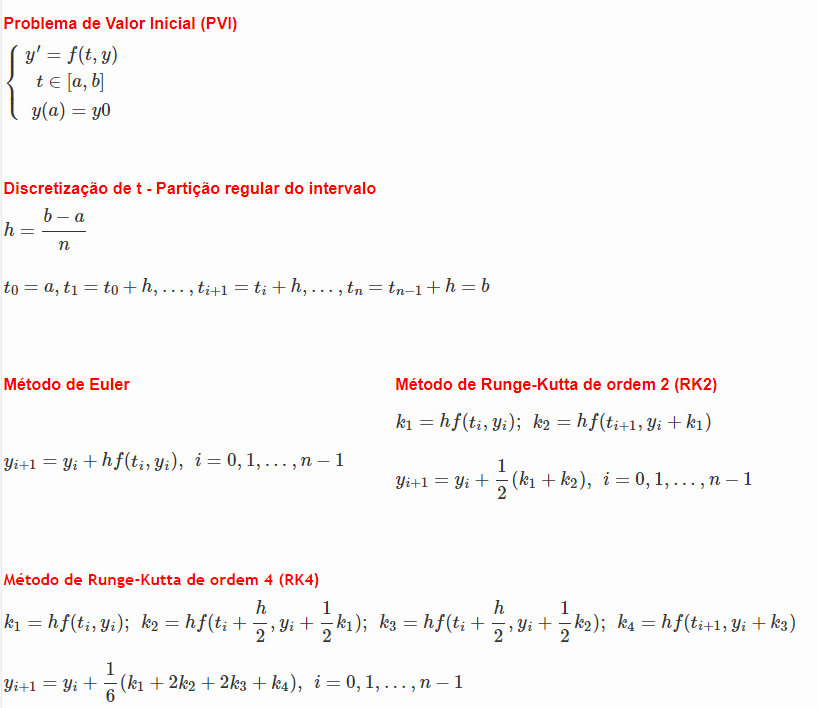

clear
syms y(t)

while 1
    %strF = input("f(t,y) = ","s");
    strF = "-2*t*y";
    f =@(t,y) eval(vectorize(strF));
    try
        fTeste = f(t,y);
        break
    catch ME
        waitfor(errordlg("Introduza uma função em t e y","Erro")) 
    end
end

while 1
    a = 0;
    if isscalar(a) && isreal(a)
        break
    else
        waitfor(errordlg("Erro ao inserir valor de 'a'. Introduza um número real.", "Erro"));
        break
    end
end

while 1
    b = 1.5;
    if isscalar(b) && isreal(b) && b>a
       break
    else
        waitfor(errordlg("Erro ao inserir valor de 'b'. Introduza um número real maior que 'a'.", "Erro"));
        break
    end
end
while 1
    n = 2;
    if  isscalar(n) && isreal(n) && n>=2
        break
   else
        waitfor(errordlg("Erro ao inserir valor de 'n'. Introduza um número real positivo  e maior ou igual a 2.", "Erro"));
        break
    end
end

while 1
    y0 = 2;
     if isscalar(y0) && isreal(y0) 
        break
     else
        waitfor(errordlg("Erro ao inserir valor de 'y0'. Introduza um número real.", "Erro"));
        break
     end
end

%Chamar as funções

yEuler = Euler(f,a,b,n,y0);
yEulerM = EulerM(f,a,b,n,y0);
yRK2 = RK2(f,a,b,n,y0);
yRK4 = RK4(f,a,b,n, y0);
yODE45 = ODE45 (f,a,b,n,y0);
yPM = PM(f,a,b,n,y0);

% Calcular e mostrar o gráfico da solução exata
sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0);
disp(['Solução exata = ' char(sExata)]);

Solução exata = 2*exp(-t^2)


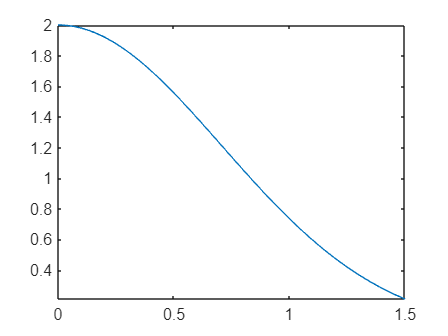

fplot(sExata,[a,b])


g =@(t) eval(vectorize(char(sExata)));

h = (b-a)/n;
t = a:h:b;
yExata = g(t);

%Calcular os erros
erroEuler = abs(yExata-yEuler);
erroEulerM = abs(yExata-yEulerM);
erroRK2 = abs(yExata-yRK2);
erroRK4 = abs(yExata-yRK4);
erroODE45 = abs(yExata-yODE45);
erroPM = abs(yExata-yPM);

plot(t,yExata,"-ro")
hold on
escolha = "Euler"

escolha = "Euler"

switch escolha
    case "Euler"
        tabela = [t.', yExata.', yEuler.', erroEuler.'];
        array2table(tabela, "VariableNames", {'t', 'Exata', 'Euler',  'ErroEuler'})
        plot(t,yEuler,"-g*")
        legend('Exata','Euler')
    
    case "Euler Moderado"
        tabela = [t.', yExata.', yEulerM.', erroEulerM.'];
        array2table(tabela, "VariableNames", {'t', 'Exata', 'EulerM',  'ErroEulerM'})
        plot(t,yEulerM,"-m*")
        legend('Exata','EulerM')
    
    case "RK2"
        tabela = [t.', yExata.', yRK2.', erroRK2.'];
        array2table(tabela, "VariableNames", {'t', 'Exata', 'RK2',  'ErroRK2'})
        plot(t,yRK2,"-b+")
        legend('Exata','RK2')
    
    case "RK4"
        tabela = [t.', yExata.', yRK4.', erroRK4.'];
        array2table(tabela, "VariableNames", {'t', 'Exata', 'RK4',  'ErroRK4'})
        plot(t,yRK4,"-k+")
        legend('Exata','RK4')
    
    case "ODE45"
        tabela = [t.', yExata.', yODE45.', erroODE45.'];
        array2table(tabela, "VariableNames", {'t', 'Exata', 'ODE45',  'ErroODE45'})
        plot(t,yODE45,"-y+")
        legend('Exata','ODE45')
    
    case "Ponto Médio"
        tabela = [t.', yExata.', yPM.', erroPM.'];
        array2table(tabela, "VariableNames", {'t', 'Exata', 'PM',  'ErroPM'})
        plot(t,yPM,"-c+")
        legend('Exata','PM')

    
    case "Todos"
        tabela = [t.', yExata.', yEuler.',yEulerM.', yRK2.', yRK4.',yODE45.',yPM.', erroEuler.', erroEulerM.', erroRK2.', erroRK4.',erroODE45.',erroPM.'];
        array2table(tabela, "VariableNames", {'t', 'Exata', 'Euler', 'EulerM','RK2', 'RK4','ODE45','PM', 'ErroEuler', 'ErroEulerM','ErroRK2', 'ErroRK4','ErroODE45','ErroPM'})
        plot(t,yEuler,"-g*")
        plot(t,yEulerM,"-m*")
        plot(t,yRK2,"-b+")
        plot(t,yRK4,"-k+")
        plot(t,yODE45,"-y+")
        plot(t,yPM,"-c+")
        legend('Exata','Euler','EulerM','RK2','RK4','ODE45','PM')

end

ans = 3×4 table
     t      Exata     Euler    ErroEuler
    ____    ______    _____    _________

       0         2        2           0 
    0.75    1.1396        2     0.86043 
     1.5    0.2108    -0.25      0.4608 


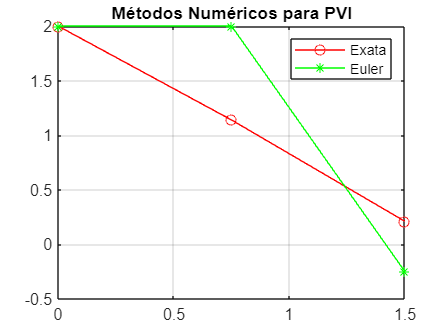

title('Métodos Numéricos para PVI')
hold off

grid on